format long
syms x_l f_l f_d(s,t,z) g_d(s,t,z)

% import the data we have 
data = importdata('FP_data_Q4.txt');
x = data(:,1);
y = data(:,2);

% interpolate more points
% find the lagrange function to interpolate more points
f_l = LagrangePolynomial(x_l,x,y)

$$L\_coeffs = \left(\begin{array}{c} \frac{128\,\left(2\,x_{l}-1\right)\,\left(x_{l}-1\right)\,\left(x_{l}-\frac{3}{2}\right)\,\left(x_{l}-\frac{3}{4}\right)\,\left(x_{l}-\frac{5}{4}\right)\,\left(x_{l}-\frac{7}{4}\right)}{315}\\ -\frac{256\,x_{l}\,\left(x_{l}-1\right)\,\left(x_{l}-\frac{3}{2}\right)\,\left(x_{l}-\frac{3}{4}\right)\,\left(x_{l}-\frac{5}{4}\right)\,\left(x_{l}-\frac{7}{4}\right)}{15}\\ \frac{512\,x_{l}\,\left(x_{l}-1\right)\,\left(x_{l}-\frac{1}{2}\right)\,\left(x_{l}-\frac{3}{2}\right)\,\left(x_{l}-\frac{5}{4}\right)\,\left(x_{l}-\frac{7}{4}\right)}{9}\\ -\frac{256\,x_{l}\,\left(x_{l}-\frac{1}{2}\right)\,\left(x_{l}-\frac{3}{2}\right)\,\left(x_{l}-\frac{3}{4}\right)\,\left(x_{l}-\frac{5}{4}\right)\,\left(x_{l}-\frac{7}{4}\right)}{3}\\ \frac{1024\,x_{l}\,\left(x_{l}-1\right)\,\left(x_{l}-\frac{1}{2}\right)\,\left(x_{l}-\frac{3}{2}\right)\,\left(x_{l}-\frac{3}{4}\right)\,\left(x_{l}-\frac{7}{4}\right)}{15}\\ -\frac{256\,x_{l}\,\left(x_{l}-1\right)\,\left(x_{l}-\frac{1}{2}\right)\,\left(x_{l}-\frac{3}{4}\right)\,\left(x_{l}-\frac{5}{4}\right)\,\left(x_{l}-\frac{7}{4}\right)}{9}\\ \frac{512\,x_{l}\,\left(x_{l}-1\right)\,\left(x_{l}-\frac{1}{2}\right)\,\left(x_{l}-\frac{3}{2}\right)\,\left(x_{l}-\frac{3}{4}\right)\,\left(x_{l}-\frac{5}{4}\right)}{105} \end{array}\right)$$

$$f\_l = -\frac{715712\,{x_{l}}^{6}}{196875}+\frac{1486312\,{x_{l}}^{5}}{65625}-\frac{2145226\,{x_{l}}^{4}}{39375}+\frac{1629949\,{x_{l}}^{3}}{26250}-\frac{50029729\,{x_{l}}^{2}}{1575000}+\frac{4304413\,x_{l}}{1050000}+1$$

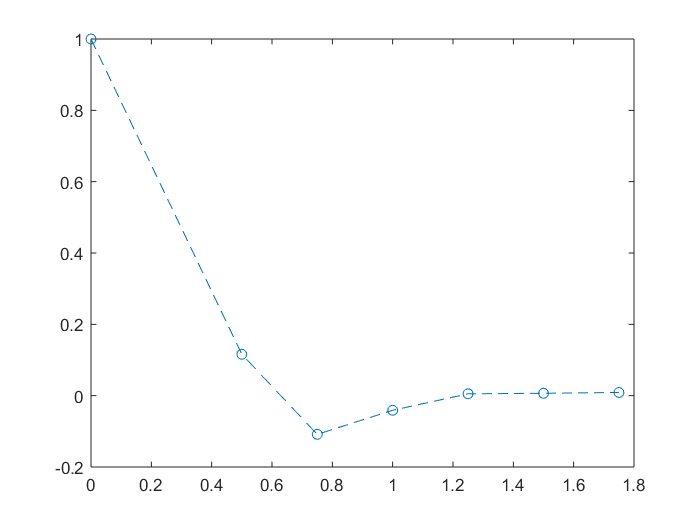

% 

% set the step size 
h = 0.25;
% set the range of points to step through
x_pts = 0:h:2;

% coefficient matrix A B C
coeffs = ones(3,1);

% input the derrivative functions associated the ODE 
f_d(s,t,z) = z;
g_d(s,t,z) = s-2*z - 4*s;

plot(x,y,'--o')